# AAE 567 HW4 Problem2

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
outdir = pwd + "\output\hw4";
mdir = pwd + "\mfiles\hw4";

m = 1;
% Define expectations 
syms x v u y g
y = x + u + v;
g = [];
for n = 0:m
    g = [g; y^n];
end
xl = 0; xu = 1;  % range of x
vl = 0; vu = 1;  % range of v
EX = @(A) int(x.^A, xl, xu);
EV = @(A) int(v.^A, vl, vu);
EY = @(A) int(int(y.^A, x, xl, xu), vl, vu);
EXY = @(A,B) int(int(x.^A * y.^B, x, xl, xu), vl, vu);

% P_Hx
Rfg = EXY(1, 0:m);

A = [];
for n = 0:m
    A = [A; n:n+m];
end
Rg = EY(A);
coef = Rfg * inv(Rg);
coef = eval(coef);
% Error d4
d4sq = EX(2) - Rfg*inv(Rg)*Rfg';
d4 = sqrt(d4sq);

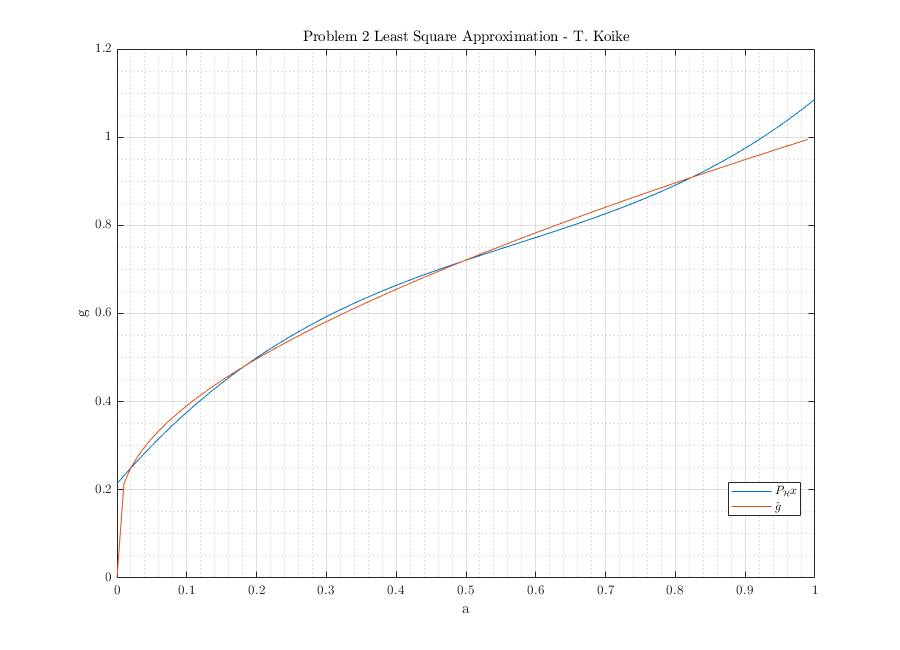

% % Plotting
% t = 0:0.01:1;
% % ghat
% Phx = 0;
% for n = 1:length(coef)
%     Phx = Phx + coef(n)*t.^(n-1);
% end
% 
% fig = figure("Renderer","painters",'Position',[60 60 900 650]);
%     plot(t, Phx)
%     grid on; grid minor; box on; hold on;
%     plot(t, (t-1)./log(t))
%     hold off;
%     title('Problem 2 Least Square Approximation - T. Koike')
%     legend('$P_{\mathcal{H}}x$', '$\hat{g}$', "Location","best")
%     xlabel('a')
%     ylabel('g')
% saveas(fig, fullfile(outdir, 'p2_lsqr_plot.png'));

% % Save file as .m
% matlab.internal.liveeditor.openAndConvert('hw4_p2.mlx', ...
%     convertStringsToChars(fullfile(mdir, 'hw4_p2.m')));
% 